clc; clear;
syms l1 l2 l3 d1 d2 d3 theta1 theta2 theta3

DH =    [l1 d1 0 0;
        l2 0 0 theta2;
        l3 0 0 theta3];
q = [0, pi/4, pi/4];
l = [1245 685 685];

bot1 = manipulator(DH,l);
T = bot1.fkine()

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & l_{1}+l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T = bot1.fkine(q)

%J = bot1.Jacobian() %Validate this result
%bot1.currentProperties



[a, b, c] = bot1.ikine([10 10 20])

a = 20

b =     1.9005    2.7957


c =     0.6756    2.4660


%T1 = bot1.fkine([d1 theta2 theta3])
Tk_plus = simplify(subs(T,{d1,theta2,theta3}, {a,b(1,1),c(1,1)}))%The plus of theta3

$$Tk\_plus = \left(\begin{array}{cccc} \cos\left(\frac{23203451585445637}{9007199254740992}\right) & -\sin\left(\frac{23203451585445637}{9007199254740992}\right) & 0 & l_{1}+l_{2}\,\cos\left(\frac{4279545017192223}{2251799813685248}\right)+l_{3}\,\cos\left(\frac{23203451585445637}{9007199254740992}\right)\\ \sin\left(\frac{23203451585445637}{9007199254740992}\right) & \cos\left(\frac{23203451585445637}{9007199254740992}\right) & 0 & l_{2}\,\sin\left(\frac{4279545017192223}{2251799813685248}\right)+l_{3}\,\sin\left(\frac{23203451585445637}{9007199254740992}\right)\\ 0 & 0 & 1 & 20\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Tk_minus = simplify(subs(T,{d1,theta2,theta3}, {a,b(1,2),c(1,2)}))%The minus of theta3

$$Tk\_minus = \left(\begin{array}{cccc} \cos\left(\frac{11848265886896511}{2251799813685248}\right) & -\sin\left(\frac{11848265886896511}{2251799813685248}\right) & 0 & l_{1}+l_{3}\,\cos\left(\frac{11848265886896511}{2251799813685248}\right)+l_{2}\,\cos\left(\frac{6295346014037257}{2251799813685248}\right)\\ \sin\left(\frac{11848265886896511}{2251799813685248}\right) & \cos\left(\frac{11848265886896511}{2251799813685248}\right) & 0 & l_{3}\,\sin\left(\frac{11848265886896511}{2251799813685248}\right)+l_{2}\,\sin\left(\frac{6295346014037257}{2251799813685248}\right)\\ 0 & 0 & 1 & 20\\ 0 & 0 & 0 & 1 \end{array}\right)$$


y = T(2,4);
x = T(1,4);
D = (y^2 + (x-l(1,1))^2 - l(1,2)^2 - l(1,3)^2)/(2*l(1,2)*l(1,3))

$$D = \frac{{\left(l_{1}+l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right)-1245\right)}^{2}}{938450}+\frac{{\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\right)}^{2}}{938450}-1$$

theta3_plus = simplify(atan2(D,sqrt(1-D^2)))

$$theta3\_plus = \text{atan2}\left(\frac{{\left(l_{1}+l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right)-1245\right)}^{2}}{938450}+\frac{{\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\right)}^{2}}{938450}-1,\frac{\sqrt{880688402500-{\left({\left(l_{1}+l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right)-1245\right)}^{2}+{\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\right)}^{2}-938450\right)}^{2}}}{938450}\right)$$

theta3_minus = simplify(atan2(D,-sqrt(1-D^2)))

$$theta3\_minus = \text{atan2}\left(\frac{{\left(l_{1}+l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right)-1245\right)}^{2}}{938450}+\frac{{\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\right)}^{2}}{938450}-1,-\frac{\sqrt{880688402500-{\left({\left(l_{1}+l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right)-1245\right)}^{2}+{\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\right)}^{2}-938450\right)}^{2}}}{938450}\right)$$

theta2 = simplify(atan2(y,x-l(1,1)) - atan2(l(1,2) + l(1,3)*cos(theta3_minus),l(1,3)*sin(theta3_minus)))

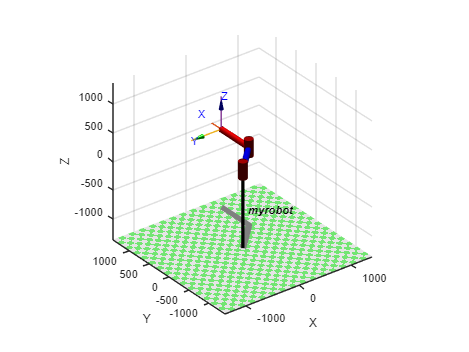


%Using robotics toolbox to confirm results
%L1 = Link('a', l(1,1), 'alpha', pi/2, 'theta', 0, 'qlim',[0 40]);
%L1 = Link('a', l(1,1),'d',0, 'alpha', 0);
L2 = Link('a', l(1,2),'d',0, 'alpha', 0);
L3 = Link('a', l(1,3),'d',0, 'alpha', 0);

bot = SerialLink([L2 L3], 'name', 'myrobot');
%T1 = bot.fkine(q)
%bot.base = trotz(pi/2);
bot.plot([pi/4 pi/4])